% clean workspace
clear all
clc
close all

% load sound file
cd /home/ben/Music/Cleaned_audio/
load('volt2pascal.mat')
[file,path] = uigetfile('*.wav');
[data,fs] = audioread(file)

data =          0
   -0.0001
   -0.0000
   -0.0001
   -0.0000
    0.0001
    0.0001
    0.0005
    0.0001
   -0.0003


fs = 250000

% convert sound file to pascal
dataPascal = data*transferFunction/gainF;

clear data

% load experiment vectors for alignment with conditions
cd /media/ben/'Extreme SSD'/analysisData/added_aligned/
[file,path] = uigetfile('condUnits_*.mat');
load(file)

% segment the sound based on the conditions
avisoftConditions.aluminumEpochs = round(alignedTimes.alignedEphys(conditionVector.aluminumEpochs))

avisoftConditions = struct with fields:
    aluminumEpochs: [11×2 double]


avisoftConditions.attenuatedEpochs = round(alignedTimes.alignedEphys(conditionVector.mutedEpochs))

avisoftConditions = struct with fields:
      aluminumEpochs: [11×2 double]
    attenuatedEpochs: [5×2 double]


avisoftConditions.noObjectEpochs = round(alignedTimes.alignedEphys(conditionVector.nonEpochs))

avisoftConditions = struct with fields:
      aluminumEpochs: [11×2 double]
    attenuatedEpochs: [5×2 double]
      noObjectEpochs: [8×2 double]


avisoftConditions.noWhiskAlum = round(alignedTimes.alignedEphys(conditionVector.noWhiskingCondition.aluminum))

avisoftConditions = struct with fields:
      aluminumEpochs: [11×2 double]
    attenuatedEpochs: [5×2 double]
      noObjectEpochs: [8×2 double]
         noWhiskAlum: [17×2 double]


avisoftConditions.noWhiskAtten = round(alignedTimes.alignedEphys(conditionVector.noWhiskingCondition.attenuted))

avisoftConditions = struct with fields:
      aluminumEpochs: [11×2 double]
    attenuatedEpochs: [5×2 double]
      noObjectEpochs: [8×2 double]
         noWhiskAlum: [17×2 double]
        noWhiskAtten: [7×2 double]


avisoftConditions.noWhiskNoO = round(alignedTimes.alignedEphys(conditionVector.noWhiskingCondition.noObject))

avisoftConditions = struct with fields:
      aluminumEpochs: [11×2 double]
    attenuatedEpochs: [5×2 double]
      noObjectEpochs: [8×2 double]
         noWhiskAlum: [17×2 double]
        noWhiskAtten: [7×2 double]
          noWhiskNoO: [14×2 double]


windowLength = 1*250000;  % For 1-second bins with fs = 250000, windowLength = 250000
overlapLength = 0*250000;
fftLength = windowLength;

aFE = audioFeatureExtractor('SampleRate', fs);

% List all available features
allFeatures = setdiff(properties(aFE), {'SampleRate', 'Window', 'OverlapLength', 'FFTLength', ...
                                        'SpectralDescriptorInput','FeatureVectorLength'});

% Set all features to true
for i = 1:length(allFeatures)
    set(aFE, allFeatures{i}, true);
end
set(aFE, 'pitch', false);
set(aFE, 'Window', hamming(windowLength), ...
                   'OverlapLength', overlapLength, ...
                   'FFTLength', fftLength);


set(aFE,'melSpectrum',false)
set(aFE,'linearSpectrum',true)
set(aFE,'melSpectrum',false)
set(aFE,'barkSpectrum',false)
set(aFE,'erbSpectrum',false)
set(aFE,'mfcc',false)
set(aFE,'mfccDelta',false)
set(aFE,'mfccDeltaDelta',false)
set(aFE,'gtcc',false)
set(aFE,'gtccDelta',false)
set(aFE,'gtccDeltaDelta',false)

% Initialize an empty matrix or table to store features and labels
allFeatures = [];  
allLabels = {};  % to store corresponding class labels
allEndIndices = [];
allStartIndices = [];
whiskingBinary = [];

classMatrices = {avisoftConditions.aluminumEpochs, avisoftConditions.attenuatedEpochs, avisoftConditions.noObjectEpochs,avisoftConditions.noWhiskAlum,avisoftConditions.noWhiskAtten,avisoftConditions.noWhiskNoO};  % replace with actual matrices
classNames = {'Aluminum', 'Attenuated', 'No object','Aluminum', 'Attenuated', 'No object'};  

stepSize = windowLength - overlapLength;  % Step size adjusted for overlap

for classIdx = 1:length(classMatrices)
    currClassMatrix = classMatrices{classIdx};
    
    for i = 1:size(currClassMatrix, 1)
        % Check for NaN values in the current epoch
        if any(isnan(currClassMatrix(i, :)))
            fprintf('Skipping epoch %d in class %s due to NaN values.\n', i, classNames{classIdx});
            continue;  % skip to the next epoch
        end
        
        % Extract segment from audio data for the current epoch
        startSample = currClassMatrix(i, 1);
        endSample = currClassMatrix(i, 2);
        segment = dataPascal(startSample:endSample);
        
        % Extract features for the entire segment
        features = extract(aFE, segment);
        
        % Use buffer to get start and end indices of each window
        if length(segment) <= windowLength
            fprintf('Skipping segment %d in class %s due to length.\n', i, classNames{classIdx});
            continue
        end
        indexBuffer = buffer(startSample:endSample, windowLength, overlapLength,"nodelay");
        startIndicesSegment = indexBuffer(1, :);  % First row contains start indices
        endIndicesSegment = indexBuffer(end, :);  % Last row contains end indices
        startIndicesSegment(endIndicesSegment == 0) = [];
        endIndicesSegment(endIndicesSegment == 0) = [];
        
        
        numWindows = length(endIndicesSegment);
        
        % Store the features, class label, and indices
        currentLabels = repmat({classNames{classIdx}}, numWindows, 1);
        if classIdx < 4
            currentWhisk = ones(numWindows,1);
        elseif classIdx > 3
            currentWhisk = zeros(numWindows,1);
        end
        whiskingBinary = [whiskingBinary;currentWhisk];
        allFeatures = [allFeatures; features];
        allLabels = [allLabels; currentLabels];
        allStartIndices = [allStartIndices; startIndicesSegment'];
        allEndIndices = [allEndIndices; endIndicesSegment'];
    end
end

Skipping segment 8 in class Aluminum due to length.


Skipping epoch 9 in class Aluminum due to NaN values.
Skipping epoch 10 in class Aluminum due to NaN values.
Skipping epoch 11 in class Aluminum due to NaN values.


Skipping segment 2 in class Aluminum due to length.
Skipping segment 5 in class Aluminum due to length.
Skipping segment 11 in class Aluminum due to length.


Skipping epoch 15 in class Aluminum due to NaN values.
Skipping epoch 16 in class Aluminum due to NaN values.
Skipping epoch 17 in class Aluminum due to NaN values.


Skipping segment 6 in class Attenuated due to length.
Skipping segment 4 in class No object due to length.
Skipping segment 8 in class No object due to length.
Skipping segment 10 in class No object due to length.


featureInfo = info(aFE);
linearSpecLength = length(featureInfo.linearSpectrum);
allFeaturesDown = allFeatures;
linearSpecNum = featureInfo.linearSpectrum

linearSpecNum =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% Extract the linearSpectrum columns from allFeatures
linearSpectrumCols = allFeatures(:, 1:linearSpecLength);

% Apply the averaging method to coarsen the linearSpectrum resolution
desiredResolution = 1000; % Example: 1000 Hz bandwidth per bin
coarseLinearSpectrum = arrayfun(@(i) averageSpectrumBins(linearSpectrumCols(i, :), desiredResolution, fs, windowLength), 1:size(linearSpectrumCols, 1), 'UniformOutput', false);
coarseLinearSpectrum = cell2mat(coarseLinearSpectrum');


% Replace the original linearSpectrum columns in allFeatures with the coarsened version
allFeaturesDown(:, 1:linearSpecLength) = []

allFeaturesDown = 1.0e+05 *

    0.2197    0.0019    0.0000    0.0000    0.0000         0    0.0001    0.3937    0.0000   -0.0000    0.0933    0.0000    0.0000    0.0000
    0.1981    0.0013    0.0000    0.0000    0.0000    0.0000    0.0002    0.3746    0.0000   -0.0000    0.1156    0.0000    0.0000    0.0000
    0.2346    0.0040    0.0000    0.0000    0.0000    0.0000    0.0001    0.3939    0.0000   -0.0000    0.1169    0.0000    0.0000    0.0000
    0.2296    0.0065    0.0000    0.0000    0.0000    0.0000    0.0001    0.4361    0.0000   -0.0000    0.1414    0.0000    0.0000    0.0000
    0.2199    0.0027    0.0000    0.0000    0.0000    0.0000    0.0001    0.5188    0.0000   -0.0000    0.1169    0.0000    0.0000    0.0000
    0.2052    0.0017    0.0000    0.0000    0.0000    0.0000    0.0002    0.3767    0.0000   -0.0000    0.0832    0.0000    0.0000    0.0000
    0.1981    0.0046    0.0000    0.0000    0.0000    0.0000    0.0003    0.3773    0.0000   -0.0000    0.0834    0.0000    0

allFeaturesDown = [coarseLinearSpectrum,allFeaturesDown]

allFeaturesDown = 1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

    
% Now, the linearSpectrum columns in allFeatures have been coarsened, and the rest of the features remain unchanged.


% Initialize cell array to store feature names
featureNames = {};

% Generate names for the coarsened linearSpectrum
numBins = size(coarseLinearSpectrum, 2);  % Determine the number of frequency bands in the coarsened spectrum
for j = 1:numBins
    featureName = sprintf('linearSpectrum_%d', j);
    featureNames = [featureNames; featureName];
end

% Extract the names of the other 14 features from featureInfo
featureInfo = info(aFE);
fields = fieldnames(featureInfo);
for i = 1:length(fields)
    % Skip linearSpectrum since we already handled it
    if strcmp(fields{i}, 'linearSpectrum')
        continue;
    end
    
    fieldData = featureInfo.(fields{i});
    
    % If the field data has multiple IDs, append an index to the feature name
    if numel(fieldData) > 1
        for j = 1:numel(fieldData)
            featureName = sprintf('%s_%d', fields{i}, j);
            featureNames = [featureNames; featureName];
        end
    else
        % Otherwise, just append the field name
        featureNames = [featureNames; fields{i}];
    end
    end


featuresTable = array2table(allFeaturesDown, 'VariableNames', featureNames);


adjustedSamplesAll = [adjustedSamples.Aluminum,adjustedSamples.Attenuated,adjustedSamples.noObject,adjustedSamples.NoWhisking]

adjustedSamplesAll = 1.0e+07 *

    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844    1.9844


adjustedSDF = zeros(size(referance_table,1),length(adjustedSamplesAll))

adjustedSDF =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

adjustedFR = zeros(size(referance_table,1),length(adjustedSamplesAll))

adjustedFR =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

for i = 1:size(adjustedSDF,1)
    tempSDF = [referance_table.AluminumSDF{i};referance_table.AttenuatedSDF{i};referance_table.NoObjectSDF{i};referance_table.NoWhiskingSDF{i}];
    tempFR = [referance_table.AluminumBinnedFR{i};referance_table.AttenuatedBinnedFR{i};referance_table.NoObjectBinnedFR{i};referance_table.NoWhiskingBinnedFR{i}];

    adjustedSDF(i,:) = tempSDF;
    adjustedFR(i,:) = tempFR;

end

startEphys = alignedTimes.alignedAvi(allStartIndices);
endEphys = alignedTimes.alignedAvi(allEndIndices);

endAligned = [];
startAligned = [];
unitsBinned = [];
whiskEnd = [];
whiksStart = [];
whiksBinned = [];
FRBinned = [];
for ind = 1:length(startEphys)
    [~,endTemp] = min(abs(adjustedSamplesAll-endEphys(ind)));
    [~,startTemp] = min(abs(adjustedSamplesAll-startEphys(ind)));
    [~,endTempWhisk] = min(abs(whiskingVec(:,1)-endEphys(ind)));
    [~,startTempWhisk] = min(abs(whiskingVec(:,1)-startEphys(ind)));
    whiskEnd(ind) = endTempWhisk;
    whiksStart(ind) = startTempWhisk;
    endAligned(ind) = endTemp;
    startAligned(ind) = startTemp;
    unitsTemp = mean(adjustedSDF(:,startTemp:endTemp),2);
    whiskTemp = mean(whiskingVec(startTempWhisk:endTempWhisk,2));
    FRTemp = mean(adjustedFR(:,startTemp:endTemp),2);
    whiksBinned(ind) = whiskTemp;
    unitsBinned(:,ind) = unitsTemp; 
    FRBinned(:,ind) = FRTemp; 
end

additionalFeatures = table(whiksBinned',whiskingBinary,allLabels,'VariableNames',{'Whisking','binaryWhisk','Condition'})

additionalFeatures = 1338×3 table
    Whisking    binaryWhisk     Condition  
    ________    ___________    ____________

     26.554          1         {'Aluminum'}
     19.725          1         {'Aluminum'}
     18.557          1         {'Aluminum'}
     26.148          1         {'Aluminum'}
     26.198          1         {'Aluminum'}
     28.164          1         {'Aluminum'}
     25.788          1         {'Aluminum'}
     28.753          1         {'Aluminum'}
     27.962          1         {'Aluminum'}
     30.155          1         {'Aluminum'}
     25.936          1         {'Aluminum'}
     23.035          1         {'Aluminum'}
     30.091          1         {'Aluminum'}
     32.988          1         {'Aluminum'}
     29.186          1         {'Aluminum'}
     21.604          1         {'Aluminum'}


interactionT = {};

for i = 1:length(allLabels)
    if whiskingBinary(i) == 0
        tempLabel =     {['NW' strjoin(allLabels(i))]};
        interactionT(i) = tempLabel;
    else
        interactionT(i) = allLabels(i);
    end
end


 fullFeatureTable = [featuresTable,additionalFeatures,array2table(interactionT','VariableNames',{'SubCondition'})];

numUnits = size(referance_table,1);
variableNames = cell(1, size(referance_table,1));

for i = 1:numUnits
    variableNames{i} = sprintf('responseUnit%d', referance_table.unitID(i));
end


responseTable = array2table(unitsBinned','VariableNames',variableNames)

responseTable = 1338×31 table
    responseUnit70    responseUnit75    responseUnit179    responseUnit250    responseUnit261    responseUnit282    responseUnit387    responseUnit434    responseUnit34    responseUnit91    responseUnit96    responseUnit97    responseUnit111    responseUnit128    responseUnit138    responseUnit147    responseUnit151    responseUnit155    responseUnit184    responseUnit233    responseUnit234    responseUnit285    responseUnit287    responseUnit289    responseUnit293    responseUnit314    responseUnit326    

fulltable = [fullFeatureTable,responseTable]

fulltable = 1338×174 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26

cv_p = cvpartition(fullFeatureTable.Condition,"HoldOut",0.1,'Stratify', true)

cv_p = Hold-out cross validation partition
   NumObservations: 3323
       NumTestSets: 1
         TrainSize: 2991
          TestSize: 332

feature_test = fullFeatureTable(cv_p.test,:)

feature_test = 332×143 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26<

feature_train = fullFeatureTable(cv_p.training,:)

feature_train = 2991×143 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_2

response_train = responseTable(cv_p.training,:)

response_train = 2991×31 table
    responseUnit70    responseUnit75    responseUnit179    responseUnit250    responseUnit261    responseUnit282    responseUnit387    responseUnit434    responseUnit34    responseUnit91    responseUnit96    responseUnit97    responseUnit111    responseUnit128    responseUnit138    responseUnit147    responseUnit151    responseUnit155    responseUnit184    responseUnit233    responseUnit234    responseUnit285    responseUnit287    responseUnit289    responseUnit293    responseUnit314    responseUnit326   

response_test = responseTable(cv_p.test,:)

response_test = 332×31 table
    responseUnit70    responseUnit75    responseUnit179    responseUnit250    responseUnit261    responseUnit282    responseUnit387    responseUnit434    responseUnit34    responseUnit91    responseUnit96    responseUnit97    responseUnit111    responseUnit128    responseUnit138    responseUnit147    responseUnit151    responseUnit155    responseUnit184    responseUnit233    responseUnit234    responseUnit285    responseUnit287    responseUnit289    responseUnit293    responseUnit314    responseUnit326    <

[coeff, score, ~, ~, explained] = pca(table2array(response_train))

coeff =     0.2295    0.1382   -0.1895    0.0111    0.0986    0.1300    0.1939    0.1159    0.0275   -0.0216    0.0933   -0.1544   -0.0955   -0.0317    0.0185    0.5470    0.0465    0.1172   -0.2813   -0.0538    0.1806    0.1075    0.0461    0.1877    0.2794    0.1681   -0.2859    0.2193   -0.1763    0.1125   -0.1084
   -0.1648   -0.0229   -0.1195    0.2580    0.1207    0.0741    0.3946   -0.1311    0.0563    0.1479    0.1284    0.3440    0.1650    0.2774    0.1108   -0.2501    0.0060    0.0217    0.0881    0.0434    0.1805    0.2453    0.4244   -0.0975    0.0459    0.0002   -0.1805   -0.0044   -0.0572    0.1550   -0.0716
    0.1909    0.2601    0.0343   -0.0191   -0.1856   -0.0926    0.1598    0.1312    0.0034   -0.1120   -0.2378    0.0887   -0.3421    0.1136    0.1932   -0.1904    0.1491    0.4130   -0.0625   -0.0213    0.0539    0.1271   -0.2680   -0.3765   -0.1707   -0.0892   -0.1973   -0.0712   -0.1088   -0.0275   -0.0678
    0.2182   -0.0628    0.0141    0.2272   -0.0633   -0.307

score =     3.1763    0.6194    0.8291   -2.4955    1.8490    0.8415    1.9265   -0.1916    1.0014   -0.4519   -0.1108   -0.7525    1.8589   -0.4497    0.3157    0.1633   -0.4987    1.2440    1.0267    0.1815   -0.0054   -1.2134    0.1158    0.3790   -0.6309   -0.7839   -0.9493    0.8770    1.7296   -0.8089    0.7229
    3.3821    1.3025    0.2870   -2.9324    0.5866   -0.2238    1.5125    0.6471    0.5914   -0.5190   -0.3917   -0.8879    1.8324   -0.4974    0.0885   -1.2913   -0.1640    1.2955    0.2239    0.3054   -0.6226    0.1504    0.3494    2.1140    0.1856    1.0279   -1.0693    1.7723    1.0642    0.0937   -0.2868
    2.3663    2.4400    1.1411   -1.1124    0.4615    0.1277    3.2187    1.6019    0.9509   -0.4172   -1.9389   -1.1018    1.0014   -1.1486    0.7825   -0.9847   -0.1013    0.1676   -0.8588   -0.1415    0.8291   -0.2186   -2.0104    0.8923    0.9243    0.4294   -1.2339    3.2771   -0.3348    0.9234   -1.2751
    1.7184    2.3146    0.9673   -0.2601    1.7900   -0.594

explained =    20.8854
    6.5442
    5.8010
    5.0055
    4.7208
    4.0890
    3.7563
    3.3205
    3.0937
    3.0445


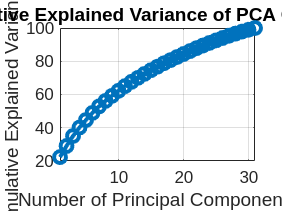

% Decide on the number of components based on explained variance
explained_cum = cumsum(explained);


% Plot
figure;
plot(explained_cum, '-o', 'LineWidth', 2);
xlabel('Number of Principal Components');
ylabel('Cumulative Explained Variance (%)');
title('Cumulative Explained Variance of PCA Coefficients');
grid on;
xlim([1, numel(explained)]);

num_components = find(explained_cum >= 95, 1) % This gives the number of components that explain 95% of the variance

num_components = 28

% Transform both training and test data using the PCA coefficients
response_train_pca = table2array(response_train) * coeff(:, 1:num_components)

response_train_pca =     3.1720    0.6325    0.8276   -2.4946    1.8478    0.8412    1.9134   -0.1840    1.0007   -0.4589   -0.1103   -0.7597    1.8524   -0.4464    0.3212    0.1681   -0.4967    1.2464    1.0231    0.1786   -0.0012   -1.2192    0.1212    0.3833   -0.6278   -0.7808   -0.9535    0.8805
    3.3778    1.3157    0.2855   -2.9314    0.5854   -0.2242    1.4993    0.6546    0.5908   -0.5261   -0.3912   -0.8952    1.8259   -0.4942    0.0940   -1.2865   -0.1620    1.2979    0.2204    0.3025   -0.6184    0.1445    0.3548    2.1183    0.1887    1.0309   -1.0736    1.7758
    2.3620    2.4531    1.1396   -1.1115    0.4603    0.1273    3.2056    1.6094    0.9503   -0.4242   -1.9384   -1.1090    0.9949   -1.1453    0.7880   -0.9799   -0.0992    0.1700   -0.8623   -0.1443    0.8334   -0.2244   -2.0050    0.8965    0.9274    0.4324   -1.2381    3.2807
    1.7141    2.3277    0.9659   -0.2592    1.7888   -0.5946    2.3662    0.7907    1.1630   -0.3179   -3.1677   -0.7024   -0.1675   -0.

response_test_pca = table2array(response_test) * coeff(:, 1:num_components)

response_test_pca =     3.6744    0.8393    0.9928    0.1767   -0.0487    1.5767    2.0106    1.1863    0.3122    0.5456   -2.1689   -0.7297    1.0204   -1.0305   -0.3650    1.5162    0.3558    0.0333   -0.3109    0.1335    0.6652    0.0491    0.5860   -0.2703    0.0875   -1.3160    0.5932   -0.4096
    0.4469    0.5101    1.8036   -0.5668    2.0108    0.3845   -1.6354    1.4929    0.3706   -0.7281    0.3416   -0.3358    0.6857    1.4824    0.3170    0.0819    1.2755    1.1356   -0.1879    0.1603   -1.1696    0.6808   -0.2377    1.4134    0.0583   -1.2990   -0.7342    0.4495
    1.2344   -0.0188    0.5989   -1.5205   -0.2337   -1.1977    0.8957   -0.2713   -0.0437    0.9266    0.3591   -0.4216   -0.6631   -0.1407    0.3595    0.0623   -0.0836   -0.0384   -0.0898   -2.5756   -1.3724   -0.9678    0.9822    0.3958    0.2270    0.0171   -0.0036    0.8183
    1.0215   -0.1874    0.1485   -3.2672    0.0829    0.5152    0.9964    1.6399   -1.0517    0.1822    0.2652   -1.6182    0.2575    0.8

featureSound = feature_train(:,1:140)

featureSound = 2991×140 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26

[soundZ,mu,sigma] = zscore(table2array(featureSound))

soundZ =     0.0909   -0.0598   -0.0495   -0.1006   -0.0844   -0.0704   -0.0717   -0.1051   -0.0929    0.8421    1.2055    2.2240    3.0218    3.3226    3.6156    6.4339    4.9239    2.2446    1.8241    5.5881    4.5198    3.6880    4.6845    4.5426    6.2314   12.6788    4.1302    8.9171   13.2182    6.2483    0.6186    0.5311    2.4062    1.2292    1.5581    1.4847    3.0602    6.0138    2.6611    3.9188    3.5206    3.1842    2.4258    9.1781    4.0888    1.2490    0.3467    0.5515    0.8320    0.9121
    1.8936   -0.0523   -0.0497   -0.0982   -0.1755   -0.0718   -0.0738   -0.1084   -0.1090   -0.1263    1.0680    0.4743    0.0667    0.3373    1.6616    0.1112   -0.1005    0.3099    0.4523    1.6698    0.5187    0.9380    0.5408    0.2711    0.5684    0.5703    0.0757    1.7918    1.3977    0.6191    0.2470    0.1317    0.7285    1.4342    1.3951    1.8690    2.1495    1.6385    1.5496    0.5998    0.0317    0.0354    0.6003    0.4491    0.9551    0.0853   -0.0296   -0.0236    0.0174

mu = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


sigma = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


soundTest = feature_test(:,1:140)

soundTest = 332×140 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26

soundTestZ = (table2array(soundTest) - mu)./sigma

soundTestZ =    -0.1732   -0.0596   -0.0495   -0.1116   -0.1693   -0.0597   -0.0814   -0.0459   -0.0932   -0.1011    1.5530    2.3980    6.2505    3.0944    3.7339    2.7592    4.3387    4.0009    7.3068   14.9679    6.2810    4.6972    4.8991    7.2946   13.2324    7.5779   20.8936    7.6769    2.5862    3.3292    1.2754    2.4619    1.9919    4.5046    3.2716    5.0963    4.8637    4.0035    8.1442   12.8293    7.1337    1.9076    1.8907    0.8006    2.1860    0.0457    1.5439    0.3089    1.2913    1.8423
   -0.1234   -0.0554   -0.0458   -0.0981   -0.0867   -0.0577   -0.0706   -0.1067   -0.1151   -0.1452    2.1566    1.8620    0.7806    2.6035    2.4320   -0.0689   -0.0255   -0.0092    0.3816    1.3245    0.4441    0.9994    0.5646    0.0405    0.6919    1.1941   -0.1161    0.2922    2.1810    1.2415    0.6493   -0.0906   -0.0370    0.1059    0.0421   -0.1807    0.0406    0.0781   -0.2742    0.0485   -0.1394   -0.0854   -0.1075    0.1126    0.8430    0.0874   -0.0435    0.1687   -0.

featureNames = [featureNames;'Whisking']

featureNames = 140×1 cell array
    {'linearSpectrum_1' }
    {'linearSpectrum_2' }
    {'linearSpectrum_3' }
    {'linearSpectrum_4' }
    {'linearSpectrum_5' }
    {'linearSpectrum_6' }
    {'linearSpectrum_7' }
    {'linearSpectrum_8' }
    {'linearSpectrum_9' }
    {'linearSpectrum_10'}
    {'linearSpectrum_11'}
    {'linearSpectrum_12'}
    {'linearSpectrum_13'}
    {'linearSpectrum_14'}
    {'linearSpectrum_15'}
    {'linearSpectrum_16'}
    {'linearSpectrum_17'}
    {'linearSpectrum_18'}
    {'linearSpectrum_19'}
    {'linearSpectrum_20'}
    {'linearSpectrum_21'}
    {'linearSpectrum_22'}
    {'linearSpectrum_23'}
    {'linearSpectrum_24'}
    {'linearSpectrum_25'}
    {'linearSpectrum_26'}
    {'linearSpectrum_27'}
    {'linearSpectrum_28'}
    {'linearSpectrum_29'}
    {'linearSpectrum_30'}


trainTable = array2table(soundZ,'VariableNames',featureNames)

trainTable = 2991×140 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26</

testTable = array2table(soundTestZ,'VariableNames',featureNames)

testTable = 332×140 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26

trainTable = [trainTable,feature_train(:,141:end)]

trainTable = 2991×143 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26</

trainTable1 = [trainTable(end,:)]

trainTable1 = 1×143 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26

trainTable2 = [trainTable(1:end-1,:)]

trainTable2 = 2990×143 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26<

trainTable = [trainTable1;trainTable2]

trainTable = 2991×143 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26</

testTable = [testTable,feature_test(:,141:end)]

testTable = 332×143 table
    linearSpectrum_1    linearSpectrum_2    linearSpectrum_3    linearSpectrum_4    linearSpectrum_5    linearSpectrum_6    linearSpectrum_7    linearSpectrum_8    linearSpectrum_9    linearSpectrum_10    linearSpectrum_11    linearSpectrum_12    linearSpectrum_13    linearSpectrum_14    linearSpectrum_15    linearSpectrum_16    linearSpectrum_17    linearSpectrum_18    linearSpectrum_19    linearSpectrum_20    linearSpectrum_21    linearSpectrum_22    linearSpectrum_23    linearSpectrum_24    linearSpectrum_25    linearSpectrum_26

%allModels = struct();
%pVlaues = [];
timeWindow = ['binSize',num2str(windowLength/fs*1000)]

timeWindow = 'binSize800'

dummyVarsTrain = dummyvar(categorical(trainTable.Condition));
dummyVarsTest = dummyvar(categorical(testTable.Condition));
regularPredictorsTrain = [table2array(trainTable(:,1:end-1)),dummyVarsTrain(:,1:2),dummyVarsTrain(:,1).*trainTable.binaryWhisk,dummyVarsTrain(:,2).*trainTable.binaryWhisk]

Error using  {} 
Unable to concatenate the table variables 'linearSpectrum_1' and 'Condition', because their types are double and cell.

Error in table2array (line 37)
a = t{:,:};

regularPredictorsTest = [table2array(testTable(:,1:end-1)),dummyVarsTest(:,1:2),dummyVarsTest(:,1).*testTable.binaryWhisk,dummyVarsTest(:,2).*testTable.binaryWhisk]
%metrices = struct();

% Initialize vectors to store metrics
test_r_squared = zeros(length(variableNames), 1);
test_rmse = zeros(length(variableNames), 1);
train_r_squared = zeros(length(variableNames), 1);

for unit = 1:length(variableNames)
    % Fit linear regression model
    responseColumnName = variableNames{unit}; % The name of the response column in the response_train table
    modelTable = [trainTable,response_train(:,responseColumnName)];

    % Get list of predictors
    predictors = modelTable.Properties.VariableNames;
    predictors(strcmp(predictors, responseColumnName)) = [];  % Remove 'response' from the list

    % Fit the model
    t = templateTree('MaxNumSplits', 20,'NumVariablesToSample', 'all');
    mdl = fitensemble(modelTable, responseColumnName, 'LSBoost', 60, t);

    % Evaluate model on training data
    y_train_pred = predict(mdl, modelTable(:, predictors)); % Predict using only predictor columns
    train_r_squared(unit) = 1 - sum((y_train_pred - table2array(response_train(:,responseColumnName))).^2) / ...
                            sum((table2array(response_train(:,responseColumnName)) - mean(table2array(response_train(:,responseColumnName)))).^2);

    % Evaluate model on test data
    y_test_pred = predict(mdl, testTable(:, predictors));  % Predict using only predictor columns from testTable
    test_rmse(unit) = sqrt(mean((y_test_pred - table2array(response_test(:,responseColumnName))).^2));
    test_r_squared(unit) = 1 - sum((y_test_pred - table2array(response_test(:,responseColumnName))).^2) / ...
                            sum((table2array(response_test(:,responseColumnName)) - mean(table2array(response_test(:,responseColumnName)))).^2);

    % Store the model
    allModels.(responseColumnName) = mdl;
end

% Output the metrics
fprintf('Training R^2:\n');

Training R^2:


disp(train_r_squared);

    0.9930
    0.9923
    0.9885
    0.9890
    0.9907
    0.9971
    0.9902
    0.9918
    0.9894
    0.9861
    0.9925
    0.9869
    0.9879
    0.9913
    0.9879
    0.9895
    0.9897
    0.9901
    0.9888
    0.9877
    0.9892
    0.9895
    0.9905
    0.9923
    0.9871
    0.9879
    0.9916
    0.9946
    0.9938
    0.9901
    0.9883



fprintf('Test R^2:\n');

Test R^2:


disp(test_r_squared);

   -0.1895
   -0.4975
   -0.5233
   -0.5068
   -0.1982
    0.3288
   -0.9301
   -0.1189
   -0.4003
   -0.5241
   -0.8132
   -1.1681
   -0.4806
   -2.1049
   -0.6023
   -0.5124
   -0.1982
   -0.5236
   -0.9311
   -0.5226
   -0.4882
   -0.5171
   -0.4728
   -0.0249
   -0.3806
   -0.5343
   -0.1095
   -0.1316
   -0.0884
   -0.5876
   -1.1555



fprintf('Test RMSE:\n');

Test RMSE:


disp(test_rmse);

    6.0253
    5.6989
   14.4451
   10.5281
    8.3027
    5.9469
    3.6440
   11.9360
    2.7521
    2.1821
    2.9185
    2.4361
    6.1473
    2.2831
    5.6163
   12.6336
    6.7838
    7.4300
    6.0358
    6.7708
    2.2985
    6.7769
    4.7378
    4.7208
    4.9161
    4.2352
    4.9543
    7.9075
    4.0232
    3.2963
    2.8661




% Predict on the test set
y_pred_pca = predict(mdl, testTable);

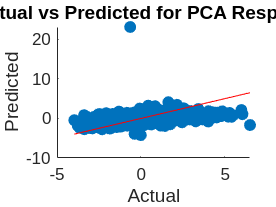


% Visualization: Actual vs. Predicted for PCA Responses
figure;
scatter(PCA1_test, y_pred_pca, 'filled');
hold on;
xlabel('Actual');
ylabel('Predicted');
title('Actual vs Predicted for PCA Responses');
line([min(PCA1_test(:)), max(PCA1_test(:))], [min(PCA1_test(:)), max(PCA1_test(:))], 'Color', 'red'); % Unity line
hold off;


% Visualization: Regression Coefficients
figure;
bar(mdl.Coefficients.Estimate);
xlabel('Predictors');
ylabel('Coefficient Value');
title('Regression Coefficients');
xticks(1:numel(mdl.CoefficientNames));
xticklabels(mdl.CoefficientNames);
xtickangle(45); % Rotate x-axis labels for better readability


% Extract coefficients and p-values
coefficients = mdl.Coefficients.Estimate;
pValues = mdl.Coefficients.pValue;

% Filter coefficients with p < 0.05
significantCoefficients = coefficients(pValues < 0.05);
significantPredictorNames = mdl.CoefficientNames(pValues < 0.05);


[~,ind] = sort(abs(significantCoefficients),'descend')

ind =      5
     4
     6
    12
    14
     1
     8
    15
    18
     9


sortedCo = significantCoefficients(ind)

sortedCo =    -0.6896
   -0.6533
    0.6510
   -0.6183
    0.5987
   -0.5572
   -0.5142
    0.4972
    0.4905
   -0.4346


predictNames = significantPredictorNames(ind)

predictNames = 1×18 cell array
    {'linearSpectrum_113'}    {'linearSpectrum_111'}    {'spectralCentroid'}    {'spectralSpread'}    {'zerocrossrate'}    {'(Intercept)'}    {'spectralEntropy'}    {'Whisking'}    {'Condition_Attenuated:binaryWhisk'}    {'spectralFlatness'}    {'linearSpectrum_102'}    {'Condition_Aluminum'}    {'linearSpectrum_97'}    {'spectralDecrease'}    {'binaryWhisk'}    {'harmonicRatio'}    {'spectralFlux'}    {'spectralKurtosis'}


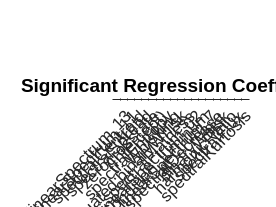


% Visualize
figure;
bar(sortedCo);
xlabel('Predictors');
ylabel('Coefficient Value');
title('Significant Regression Coefficients');
xticks(1:numel(significantPredictorNames));
xticklabels(predictNames);
xtickangle(45); % Rotate x-axis labels for better readability

writetable(fulltable, 'F103_849.csv');

% tableForExport = 

function coarseSpectrum = averageSpectrumBins(spectrum, binWidth, fs, windowLength)
    % Calculate the frequency resolution of the original spectrum
    freqResolution = fs / windowLength;
    
    % Calculate the number of bins in each averaged band
    binsPerBand = round(binWidth / freqResolution);
    
    % Determine the number of bands
    numBands = floor(length(spectrum) / binsPerBand);
    
    % Initialize the coarse spectrum
    coarseSpectrum = zeros(1, numBands);
    
    % Compute the average for each band
    for i = 1:numBands
        startIdx = (i-1) * binsPerBand + 1;
        endIdx = i * binsPerBand;
        coarseSpectrum(i) = mean(spectrum(startIdx:endIdx));
    end
end